# 案例：球面贴图

- [Zhihu: https://www.zhihu.com/people/1105936347](https://www.zhihu.com/people/1105936347)

- [Github: https://github.com/AFei19911012](https://github.com/AFei19911012)

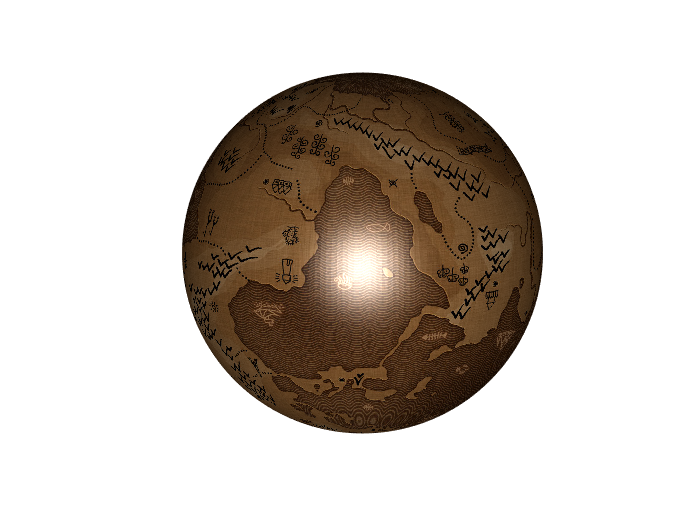

clear;clc;
% 读取地图文件
image = imread('World.jpg'); 
% 生成一个球面数据
[x, y, z] = sphere(200);
% 绘制球体
p = surf(x, y, z); 
% 去网格线
shading interp;
p.CData = image; 
% 纹理贴图
p.FaceColor = "texturemap"; 
axis equal;
axis off
% 光源，看起来更有立体感
% light
% lighting gouraud
% 光源颜色
handle = light('Color', [1 1 1]);
t = 0;
while t < 100
    t = t + 1;
    view([t 10]);
    lightangle(handle, t, 0);
    pause(0.01);
end